# Calibration Step 3 - Part 3: Processing Optimization Results

This script performs post-processing of the optimization results

Input: Data read-in from datafiles/step3/massoptimizationresults.csv

Output: posterior estimates for the m, alpha, and beta, as shown in Table 1, columns 5-7 in the paper.

## Read in the data

addpath('utilityfunctions')
nbars = 10; % number of bars for histograms
optimizationresuts = readtable('datafiles/step3/MassOptimizationResults.csv')

optimizationresuts = 100×14 table
    e_sample    target_freq_1    target_freq_2    zeta_1    zeta_2    mass_servo_1    mass_servo_2    mass_pitot    freq_1    freq_2    mean_absolute_error    mean_relative_error    servo_mass_equal    total_mass_correct
    ________    _____________    _____________    ______    ______    ____________    ____________    __________    ______    ______    ___________________    ___________________    ________________    __________________

     1.0077        5.6492            29.97     

% get servo masses. Check that it is a valid result, and convert from kg to g
servo_mass = optimizationresuts.mass_servo_1(optimizationresuts.servo_mass_equal==1 & optimizationresuts.total_mass_correct==1)*1e3;
% Get target frequencies for the optimization
target_freqs = [optimizationresuts.target_freq_1(1), optimizationresuts.target_freq_2(1)];
target_omega = 2*pi*target_freqs; %convert to angular frequency

% Get damping ratios computed in Step3_1
zeta_hat = [optimizationresuts.zeta_1(1), optimizationresuts.zeta_2(1)];

% Get optimized frequencies
optimized_freqs = [optimizationresuts.freq_1, optimizationresuts.freq_2];
optimized_omega = 2*pi*optimized_freqs;

% use optimized frequencies and damping ratios to compute Rayleigh damping coefficients alpha and beta
alpha = zeros(100,1);
beta = zeros(100,1);
for i = 1:100
    w = [optimized_omega(i,1) optimized_omega(i,2)];
    W = 0.5*[1/w(1) w(1); 1/w(2) w(2)];
    damp = W\zeta_hat';
    alpha(i) = damp(1);
    beta(i) = damp(2);
end

%Compute sample means and standard deviations
m_servo_bar = mean(servo_mass);
sigma_m_servo = std(servo_mass);

alpha_bar = mean(alpha);
sigma_alpha = std(alpha);

beta_bar = mean(beta);
sigma_beta = std(beta);

## Plot posterior for the servo mass

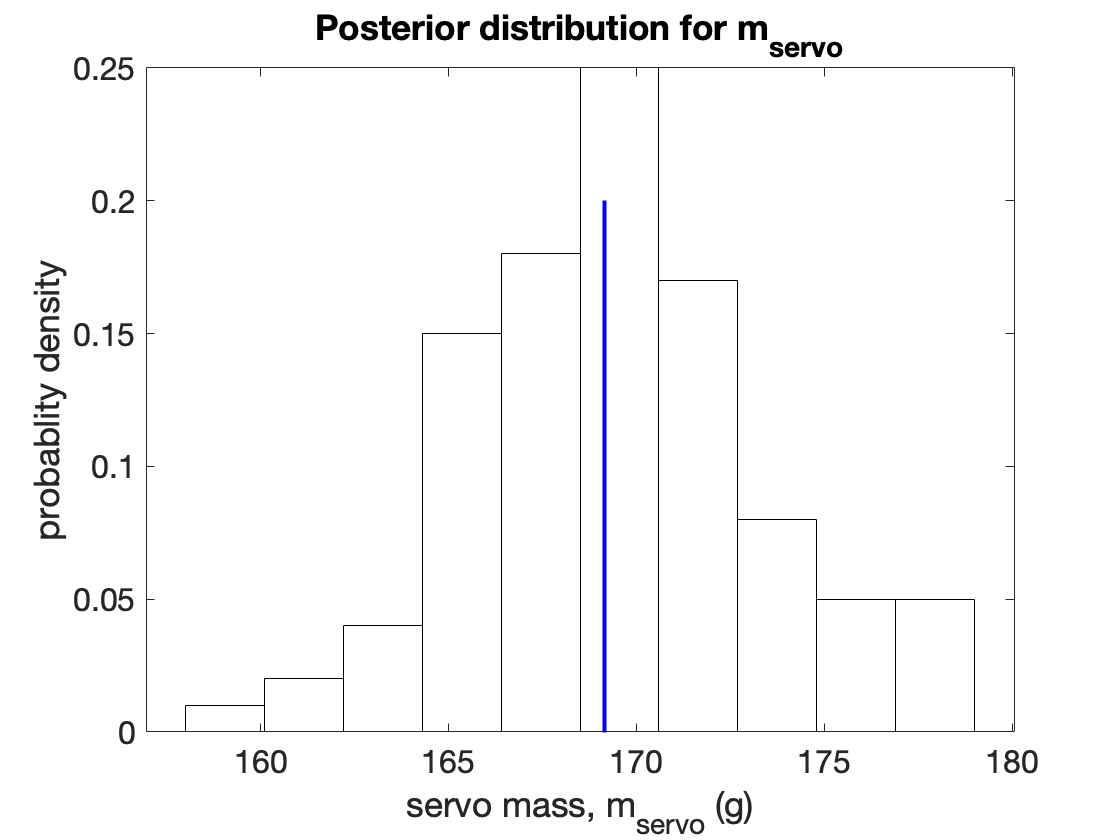

figure;
histogram(servo_mass,nbars,'FaceColor','none', 'normalization', 'probability')
hold on;
stem(m_servo_bar,0.2,'b','Linewidth',2,'marker','none')
xlabel('servo mass, m_{servo} (g)')
ylabel('probablity density')
ax = gca;
set(ax, 'FontSize', 16);
title('Posterior distribution for m_{servo}')

## Plot posterior for beta

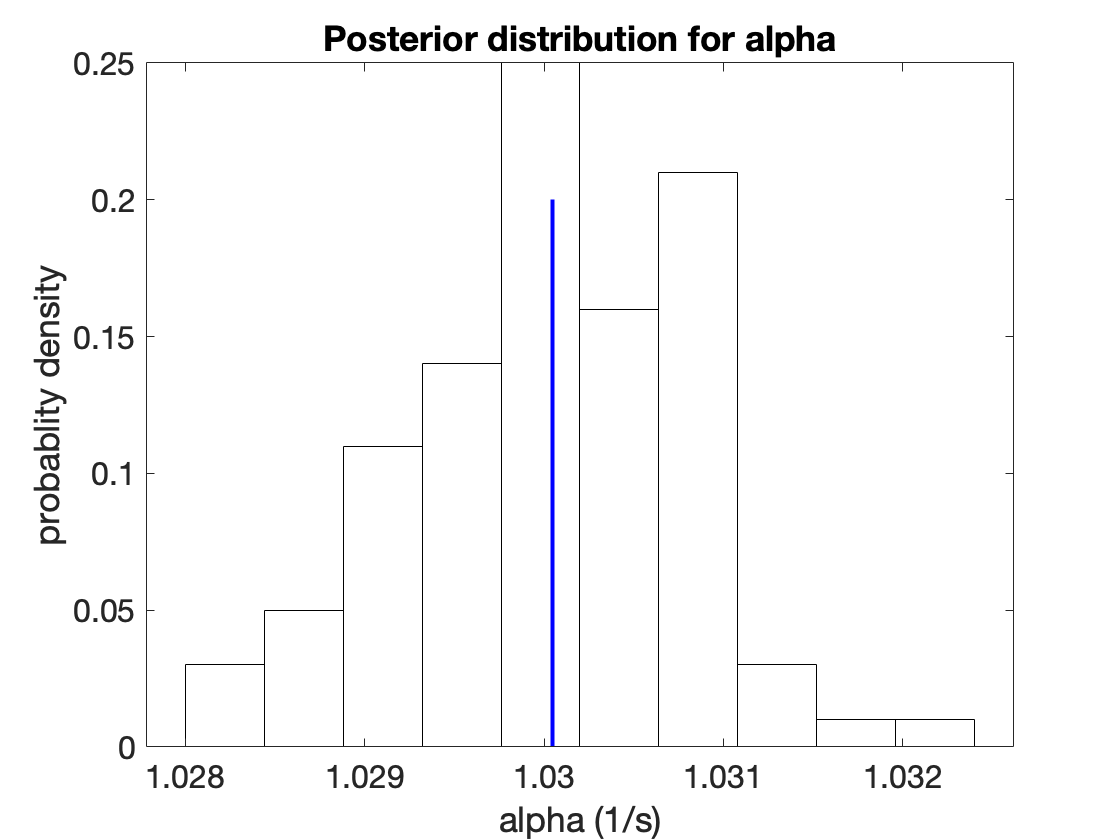

figure;
stem(alpha_bar,0.2,'b','Linewidth',2,'marker','none')
hold on;
% stem(alpha,ones(length(alpha)),'k','marker','none','Linewidth',0.5)
histogram(alpha,nbars,'FaceColor','none', 'normalization', 'probability')
xlabel('alpha (1/s)')
ylabel('probablity density')
ax = gca;
set(ax, 'FontSize', 16);
title('Posterior distribution for alpha')

## Plot posterior for beta

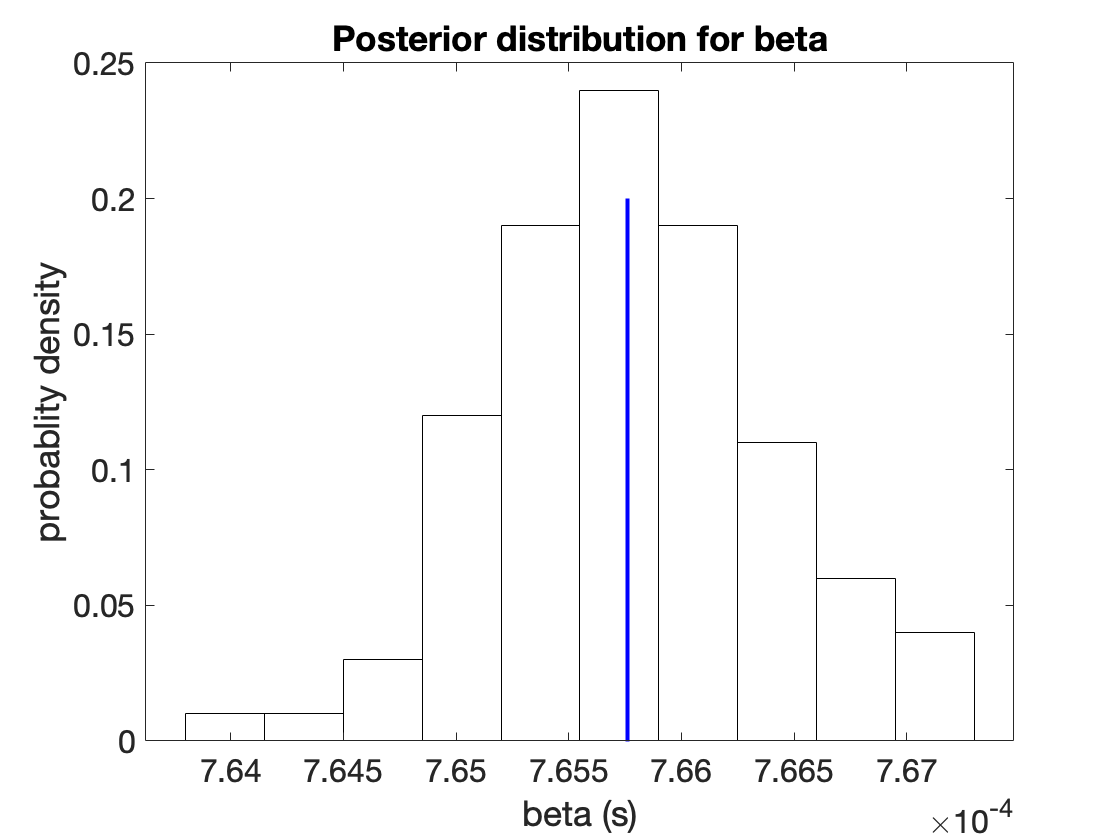

figure;
stem(beta_bar,0.2,'b','Linewidth',2,'marker','none')
hold on;
histogram(beta,nbars,'FaceColor','none', 'normalization', 'probability')
xlabel('beta (s)')
ylabel('probablity density')
ax = gca;
set(ax, 'FontSize', 16);
title('Posterior distribution for beta')